# **1.1**

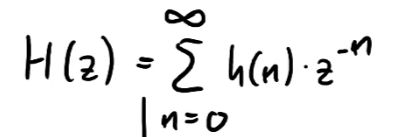

The amplitude is 1, by which we have the running sum transfer function for N=3:


$$h_{\textrm{RS}} \left(n\right)=1+z^{-1} +z^{-2} +z^{-3} =\frac{z^3 +z^2 +z+1}{z^3 }$$
 

clear all

% the polynomial coefficients stored in a vector:
numer3=[1,1,1,1];
denom3=[1,0,0,0];
% the roots are calculated:
zeros3 = roots(numer3);
poles3 = roots(denom3);

for N=5


$$h_{\textrm{RS}} \left(n\right)=1+z^{-1} +z^{-2} +z^{-3} +z^{-4} +z^{-5} =\frac{z^5 +z^4 +z^3 +z^2 +z+1}{z^5 }$$


numer5=[1,1,1,1,1,1];
denom5=[1,0,0,0,0,0];
% the roots are calculated:
zeros5 = roots(numer5);
poles5 = roots(denom5);

% plot the zplane for the 3rd order filter
figure(100)
p1 = zplane(zeros3,poles3);
title('Z-plane: Running sum filter (N = 3)')

We see that the poles and zeros match the roots of the transfer function polynomials.

There are three zeros (circles) and three poles at the origin (crosses).


figure(101)
freqz(numer3,denom3,'whole')
ylim([-40 20])
title('Frequency response: Running sum filter (N = 3)')

We see that the gain goes toward zero a number of times corresponding with the filter order, also we see that the slope of the phase is negative, until a new magnitude dip, by which the phase is shifted approximately +180.

% plot the zplane and frequency response for the 5th order filter
figure(102)
zplane(zeros5,poles5)
title('Z-plane: Running sum filter (N = 5)')
freqz(numer5,denom5,'whole')
ylim([-80 20])
title('Frequency response: Running sum filter (N = 5)')

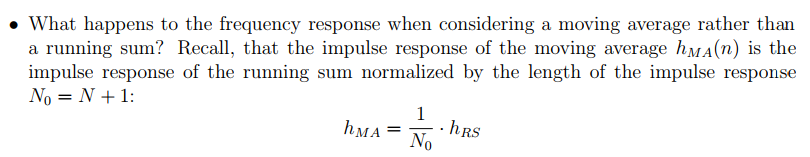

for N=3 


$$h_{\textrm{MA}} \left(n\right)=\frac{\frac{1}{4}*\left(z^3 +z^2 +z+1\right)}{z^3 }$$
 

for N=5


$$h_{\textrm{RS}} \left(n\right)=\frac{\frac{1}{6}*\left(z^5 +z^4 +z^3 +z^2 +z+1\right)}{z^5 }$$


When looking at the zeros we have: 


$$\frac{1}{6}\left(z^2 +z+1\right)=0\Leftrightarrow z^2 +z+1=0$$


Which means that the zeros placement is not gonna differ. Since the frequency plot is entirely dependent on the zeros and poles, there is not going to be a differnce in the frequency plot. This can also be seen below. 

Alas the frequency response stays the same.

%Constructing moving average filter from the above equations
denom3_MA = denom3;
numer3_MA = numer3/length(numer3);

figure(103)
freqz(numer3_MA,denom3_MA,'whole')
title('Frequency response: Moving average filter (N = 3)')
ylim([-80 20])

% MA N = 5
denom5_MA = denom5;
numer5_MA = numer5/length(numer5);

figure(104)

freqz(numer5_MA,denom5_MA,'whole')

ylim([-80 20])
title('Frequency response: Moving average filter (N = 5)')


% Lets see the difference between MA and RS for N = 5
figure(33345)
[h_5_MA,f_5_MA] = freqz(numer5_MA,denom5_MA,'whole');
h_5_RS = freqz(numer5,denom5,'whole');
f_5_MA = f_5_MA/pi;

% Magnitude plot
figure(33356)
subplot(2,1,1)
plot(f_5_MA,20*log10(abs(h_5_MA)))
ylim([-80 20])
title('Frequency response: MA vs RS (N = 5)')
ylabel('Magnitude (dB)')
xlabel('Normalized Frequency (x pi rad/sample)')
hold on
plot(f_5_MA,20*log10(abs(h_5_RS)))
hold off
legend('MA filter','RS filter')

% Phase plot
% figure(33346)
subplot(2,1,2)
plot(f_5_MA,(angle(h_5_MA)*180/pi))
ylim([-180 180])
% title('Frequency response (phase): MA vs RS (N = 5)')
ylabel('Phase (degrees)')
xlabel('Normalized Frequency (x pi rad/sample)')
hold on
plot(f_5_MA,(angle(h_5_RS)*180/pi))
hold off
legend('MA filter','RS filter')

Yes - we just flip the poles and zeros 

figure(3421)
freqz(numer3_MA,denom3_MA,'whole')
% ylim([-10 40])

re_part = cos(0.1*pi);
im_part = 1i*sin(0.1*pi);
zeros_filter = [ones(1,2)* (re_part + im_part) ones(1,2)* (re_part - im_part)];
poles_filter = [0,0,0,0];

A_filter = poly(poles_filter);
B_filter = poly(zeros_filter);
figure(105)
title('Frequency block filter')
freqz(B_filter,A_filter)
ylim([-120 30])

%Three different values of R:
R2 = 0.4;
R3 = 0.95;
R4 = 1;
A_filter2 = poly(R2*zeros_filter);
A_filter3 = poly(R3*zeros_filter);
A_filter4 = poly(R4*zeros_filter);

%For R = 0.4:
figure(106)
zplane(B_filter,A_filter2)

[h1,w1] = freqz(B_filter,A_filter);
[h2,w2] = freqz(B_filter,A_filter2);
[h3,w3] = freqz(B_filter,A_filter3);
[h4,w4] = freqz(B_filter,A_filter4);

% plotting
figure(107)
semilogy(w1,abs(h1))
title('Frequency response change with pole placement')
xlabel('Normalized Frequency (x\pi rad/sample')
ylabel('Magnitude')
hold on 
semilogy(w2,abs(h2))
semilogy(w3,abs(h3))
semilogy(w4,abs(h4))
legend('R=0','R=0.4','R=0.95','R=1')
hold off

The decrease in amplitude gets smaller as the poles move toward the zeros. As the poles reach the zeros, their effects cancel out and the magnitude response becomes constant.

# **1.2**

## ***Generating filters***

zero_fnorm = [0.3 0.4 0.6 0.8 1]; %The normalized frequency at which the zeros are placed
zero_r = [0.4 0.5 0.75 0.75 0.85]; %Their weights exp^(sigma)
zeros_lowpass = [zero_r.*(cos(zero_fnorm*pi) + 1i*sin(zero_fnorm.*pi)) zero_r.*(cos(zero_fnorm*pi) - 1i*sin(zero_fnorm.*pi))]; %complex conjugate pairs of zeros
poles_lowpass = [0.05];

B_lowpass = poly(zeros_lowpass);
A_lowpass = poly(poles_lowpass);

[H,W] = freqz(B_lowpass,A_lowpass,10000,44100);
B_lowpass = B_lowpass / H(1); % Initial value theorem.
%The DC gain of xfer function is the gain in the limit of z/s
%towards either zero or 1.

figure(108)
freqz(B_lowpass,A_lowpass)
title('Frequency response: Constructed lowpass')
%Looking at the filter on a semilogarithmic axis
[H,W] = freqz(B_lowpass,A_lowpass,10000,44100);

figure(109)
semilogx(W,20*log10(abs(H)))
xlim([100,44100/2])
%Visualizing the zeros and poles of the constructed lowpass in the Z-plane:

figure(69)
zplane(B_lowpass,A_lowpass)

Highpass:

fnorm = [0.3 0.4 0.6 0.8 1]; %The normalized frequency at which the zeros are placed
r = [0.4 0.5 0.75 0.75 0.6]; %Their weights exp^(sigma)
poles_highpass = [r.*(cos(fnorm*pi) + 1i*sin(fnorm.*pi)) r.*(cos(fnorm*pi) - 1i*sin(fnorm.*pi))];
zeros_highpass = [0.05];
B_highpass = poly(zeros_highpass);
A_highpass = poly(poles_highpass);

[H,W] = freqz(B_highpass,A_highpass);
B_highpass = B_highpass / H((length(H)));
% Final value theorem.

freqz(B_highpass,A_highpass)
title('Frequency response: Constructed highpass')
% [H,W] = freqz(poly(zeros_highpass),poly(poles_highpass),500,44100);
% semilogx(W,20*log10(abs(H)))



Allpass:

The poles and zeros must be in conjugate reciprocal pairs:

Poles: $c_i =r\cdot {\mathrm{e}}^{j\cdot \phi }$

Zeros: $\frac{1}{c_i^* }=\frac{1}{r}\cdot {\mathrm{e}}^{j\cdot \phi }$

For a first order allpass system:


$$\left|H\left(z\right)\right|=\left|\frac{z^{-1} -c^* }{1-c\cdot z^{-1} }\right|$$



$$\left|H\left({\mathrm{e}}^{j\cdot \omega } \right)\right|=\left|\frac{{\mathrm{e}}^{-j\cdot \omega } -c^* }{1-c\cdot {\mathrm{e}}^{-j\cdot \omega } }\right|=\left|\frac{{\mathrm{e}}^{-j\cdot \omega } \cdot \left(1-c^* \cdot {\mathrm{e}}^{j\cdot \omega } \right)}{1-c\cdot {\mathrm{e}}^{-j\cdot \omega } }\right|=\left|\frac{1-c^* \cdot {\mathrm{e}}^{j\cdot \omega } }{1-c\cdot {\mathrm{e}}^{-j\cdot \omega } }\right|=\left|\frac{b^* }{b}\right|=1$$


allpassorder = 5;
polemagnitude = 1/2;
%Phase shift will be 180 degrees times the filter order

poles_allpass = ones(1,allpassorder);
for k = 1:allpassorder
    poles_allpass(k) = polemagnitude*cos(k*1/allpassorder*2*pi) + 1i*polemagnitude*sin(k*1/allpassorder*2*pi);
end

zeros_allpass = ones(1,allpassorder);
%Making the zeros the reciprocal complex conjugates of the poles
for k = 1:allpassorder
    zeros_allpass(k) = 1/(conj(poles_allpass(k)));
end

B_allpass = poly(zeros_allpass);
A_allpass = poly(poles_allpass);
B_allpass = B_allpass/max(B_allpass);

figure(12)
[h_allpass,f_allpass] = freqz(B_allpass, A_allpass);
f_allpass = f_allpass/pi;

figure(13)
zplane(B_allpass, A_allpass);
title('Z-plane: Constructed allpass')

figure(664) % The neigbor of the beast
subplot(2,1,1)
plot(f_allpass,20*log10(abs(h_allpass)))
ylim([-1,1])
xlabel('Freq[Hz]')
ylabel('Magnitude[dB]')
title('Frequency response (mag): Constructed Allpass')

subplot(2,1,2)
plot(f_allpass,360/(2*pi)*angle(h_allpass))
ylim([-180,180])
xlabel('Freq[Hz]')
ylabel('Phase[degrees]')
title('Bode plot phase')
title('Frequency response (phase): Constructed Allpass')

% lets plot the low and highpass in one bode plot
[h_highpass,f_highpass] = freqz(B_highpass,A_highpass);
h_lowpass = freqz(B_lowpass,A_lowpass);

f_highpass = f_highpass/pi;

% Magnitude plot
figure(33358)
subplot(2,1,1)
plot(f_highpass,20*log10(abs(h_lowpass)))
ylim([-80 20])
title('Frequency response: low-, high-, all-pass filters')
ylabel('Magnitude (dB)')
xlabel('Normalized Frequency (x pi rad/sample)')
hold on
plot(f_highpass,20*log10(abs(h_highpass)))
plot(f_highpass,20*log10(abs(h_allpass)))
hold off
legend('Lowpass','Highpass','Allpass')

% Phase plot
% figure(33346)
subplot(2,1,2)
plot(f_highpass,(angle(h_lowpass)*180/pi))
ylim([-180 180])
% title('Frequency response (phase): MA vs RS (N = 5)')
ylabel('Phase (degrees)')
xlabel('Normalized Frequency (x pi rad/sample)')
hold on
plot(f_highpass,(angle(h_highpass)*180/pi))
plot(f_highpass,(angle(h_allpass)*180/pi))
hold off
legend('Lowpass','Highpass','Allpass')



## ***Filtering sinusoid***

[tvec, s] = generate_sinusoid(1, 10, 0, 200, 2); %a = 1, f = 10, phi = 0, fs = 200, T = 2 seconds
s_lowpass = filter(B_lowpass, A_lowpass, s);
figure(14)
plot(tvec, s_lowpass, 'linewidth',1)
hold on
plot(tvec, s, 'linewidth',1)
xlim([0.464 0.672])
ylim([-1.18 1.18])
xlabel('Time [s]')
ylabel('Amplitude')
legend('Lowpass filter output','Original sine wave (10 Hz)')
hold off

We see time delay corresponding to $\Delta t=\left|\frac{\phi^{\circ } }{360\cdot f}\right|$ 

The phase shift at 0.1 normalized frequency (10 Hz at 200 Hz sampling frequency) is about 42 degrees and corresponds to time delay of

$\frac{42}{360\cdot 10}\approx 0\ldotp 012$ s

s_highpass = filter(B_highpass, A_highpass, s);
figure(15)
plot(tvec, s_highpass, 'linewidth',1)
hold on
plot(tvec, s, 'linewidth',1)
xlim([0.464 0.672])
ylim([-1.18 1.18])
xlabel('Time [s]')
ylabel('Amplitude')
legend('Highpass filter output','Original sine wave (10 Hz)')
hold off
s_allpass = filter(B_allpass, A_allpass, s);
figure(16)
plot(tvec, s_allpass, 'linewidth',1)
hold on
plot(tvec, s, 'linewidth',1)
xlim([0.464 0.672])
ylim([-1.18 1.18])
xlabel('Time [s]')
ylabel('Amplitude')
legend('Allpass filter output','Original sine wave (10 Hz)')
hold off

No change in amplitude nor phase.

figure(200)
plot(tvec, s_lowpass,'r-', 'linewidth',1)
hold on
plot(tvec, s_highpass,'g-', 'linewidth',1)
plot(tvec, s_allpass,'k-', 'linewidth',1)
plot(tvec, s,'b-', 'linewidth',1)
xlim([0.464 0.672])
ylim([-1.18 1.18])
xlabel('Time [s]')
ylabel('Amplitude')
legend('Lowpass filter output','Highpass filter output','Allpass filter output','Original sine wave (10 Hz)')
hold off

## ***Filtering sounds (Chirp)***

[sax, fs_sax] = audioread([pwd filesep 'Sax12.wav']);
tsax = (1:length(sax))/fs_sax;

fspip = 44100;
Tpip = 2;
tspip = 1/fspip:1/fspip:Tpip-1/fspip;
pip = chirp(tspip,0,Tpip,fspip/2);
spectrogram(pip,blackman(256),'yaxis')
caxis([-50 0])
ylim([0,1]);

pip_lowpass = filter(B_lowpass, A_lowpass, pip);
figure(16)
spectrogram(pip_lowpass,blackman(256),'yaxis')
caxis([-3 0])
ylim([0,1]);

pip_highpass = filter(B_highpass, A_highpass, pip);
figure(18)
spectrogram(pip_highpass,blackman(256),'yaxis')
caxis([-3 0])
ylim([0,1]);

sound(sax, fs_sax);

The issue here is that the filter is based on normalized frequency, where the entire frequency axis is normalized with respect to the nyquist frequency $f_N =\frac{f_s }{2}$ . The sound signal is sampled at 44100 Hz. The audible spectrum for humans only goes to about 20000 Hz. So the lowpass filter in normalized frequency is not fast enough in this case to suppres the higher frequencies of sound significantly, and the highpass filter suppresses most of the frequencies in the sound signal since at 0.5 normalized frequency which in this case is about 11000 Hz, its gain is still about -15 dB.

Therefore the filters have to be adjusted for sound signals sampled at 44100 Hz to work as intended.

# **2.1**

**FIR:**


$$H\left(z\right)=\sum_{n=0}^{\textrm{delay}} h\left(n\right)\cdot z^{-n} =1\cdot z^0 +0\ldotp 6\cdot z^{-\textrm{delay}} =\frac{z^{\textrm{delay}} +0\ldotp 6}{z^{\textrm{delay}} }$$



$$y\left(n\right)=x\left(n\right)+\alpha *x\left(n-\textrm{delay}\right)$$



$$Y\left(z\right)=X\left(z\right)+a*X\left(z\right)*z^{-\textrm{delay}}$$



$$\frac{Y\left(z\right)}{X\left(z\right)}=1+a*z^{-\textrm{delay}} =\frac{z^{\textrm{delay}} +a}{z^{\textrm{delay}} }$$
    

$b_0 =1$ , $b_{1324} =0\ldotp 6$ , $a_0 =1$

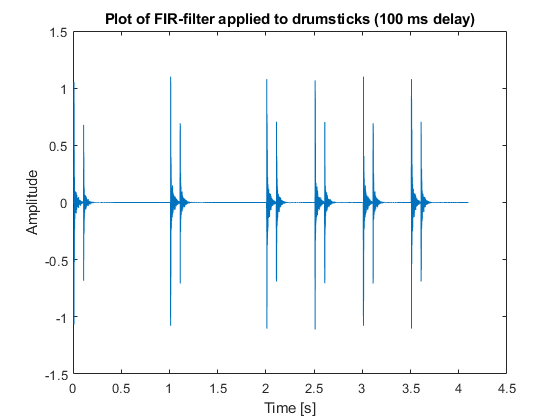

% some parameters
fs = 44100;             % sampling frequency
alpha = 0.6;             % reflection attentuation
tau = 0.1;         % delay in seconds
delay_samples = fix(tau*fs);   % calculate the delay in samples
% generate the IR
fir = [1; zeros(delay_samples - 1,1); alpha];

%Loading audio
[y, fs_y] = audioread([pwd filesep 'MUSCMisc_Drumsticks_3_ID_1969_BSB.wav']);

% Making sure that the sampling frequencies match
if (fs~=fs_y)
    fir_resample = resample(fir, fs_y, fs);
    out = circular_convolution(transpose(fir_resample), transpose(y));
else
    out = circular_convolution(transpose(fir), transpose(y));
end


figure(21)
plot((1:length(out))/fs_y, out)
ylim([-1.5,1.5])
xlabel('Time [s]')
ylabel('Amplitude')
title('Plot of FIR-filter applied to drumsticks (100 ms delay)')
xlabel('Time [s]')
ylabel('Amplitude')

As expected, the input is repeated with smaller amplitude after 0.1 seconds creating another response with smaller amplitude.

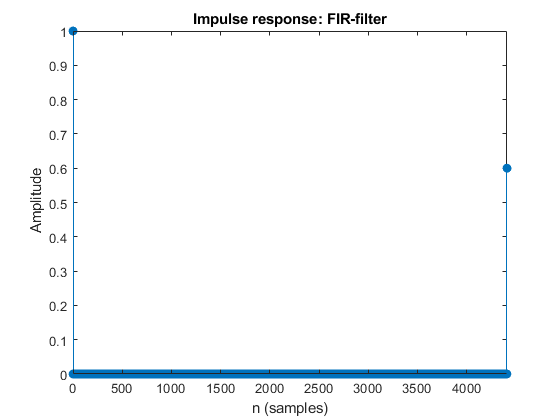

%Filter coefficients
B_fir = [1 zeros(1,delay_samples - 1) alpha];
A_fir = [1];
figure(19)
impz(B_fir, A_fir)
title('Impulse response: FIR-filter')

Audio:

           
% normalize the amplitude so that you don't blow your ears
out = out/max(out)*.5;
sound(out, fs_y)

**IIR:**


$$Y\left(z\right)+\alpha *z^{-\textrm{delay}} *Y\left(z\right)=X\left(z\right)$$



$$\left(\alpha *z^{-\textrm{delay}} +1\right)*Y\left(z\right)=X\left(z\right)$$



$$\frac{Y\left(z\right)}{X\left(z\right)}=H\left(z\right)=\frac{1}{\left(\alpha *z^{-\textrm{delay}} +1\right)}=\frac{1}{\left(\alpha *z^{-\textrm{delay}} +1\right)}*\frac{z^{\textrm{delay}} }{z^{\textrm{delay}} }=\frac{z^{\textrm{delay}} }{\left(\alpha *z^0 +z^{\textrm{delay}} \right)}=\frac{z^{\textrm{delay}} }{\left(z^{\textrm{delay}} +\alpha \right)}$$


This is just the inverse of the FIR-filter where the polynomials are swapped!

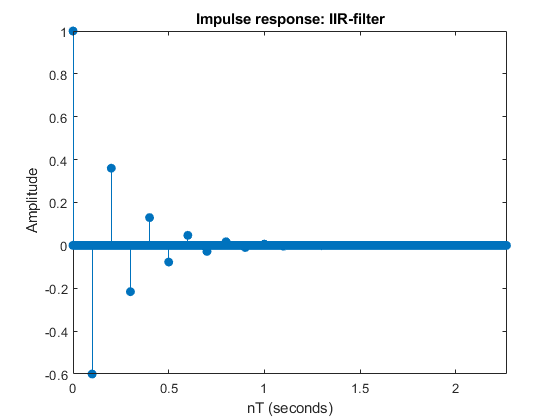

% some parameters
fs = 44100;             % sampling frequency
alpha = 0.6;            % reflection attentuation
tau = 0.1;             % delay in seconds
delay_samples = fix(tau*fs);   % calculate the delay in samples
[y, fs_y] = audioread([pwd filesep 'MUSCMisc_Drumsticks_3_ID_1969_BSB.wav']);

%Polynomial coefficients
A_iir = [1 zeros(1,delay_samples - 1) alpha];
B_iir = [1 zeros(1,delay_samples)];

% Varying the delay
tau2 = 0.01;             % delay in seconds
delay_samples2 = fix(tau2*fs);   % calculate the delay in samples

%Polynomial coefficients
A_iir2 = [1 zeros(1,delay_samples2 - 1) alpha];
B_iir2 = [1 zeros(1,delay_samples2)];


%Generating the impulse response
figure(199)
impz(B_iir,A_iir, 100000, fs)
title('Impulse response: IIR-filter')

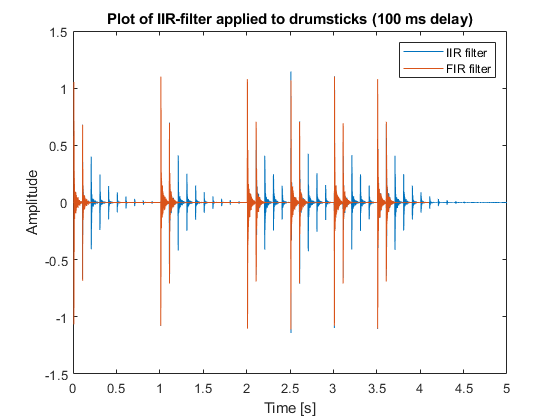

%Extracting the spectrum
[h_iir,f_iir] = freqz(B_iir,A_iir,100000,fs,'whole');
%IFFT to obtain impulse response as a vector
h_iir_ir = ifft(h_iir);

%Making sure that the sampling frequencies match
if (fs~=fs_y)
    iir_resample = resample(h_iir_ir, fs_y, fs);
    out_time = circular_convolution(transpose(iir_resample), transpose(y));
else
    out_time = circular_convolution(transpose(h_iir_ir), transpose(y));
end

t = (1:length(out_time))/fs_y;

%Plot the filter result
figure(2)
plot(t,out_time)
ylim([-1.5,1.5])
xlim([0,5])
hold on 
plot((1:length(out))/fs_y, out)
hold off
title('Plot of IIR-filter applied to drumsticks (100 ms delay)')
xlabel('Time [s]')
ylabel('Amplitude')
legend('IIR filter','FIR filter')

The output repeats and gets more and more attenuation for every reflection as expected.

The IIR-element is a result of feedback being present instead of feedforward as in the FIR.

Audio:

% sound(y,fs_y)
sound(out_time,fs_y)